Author： 黃仕鈞

# Autoregressive Modeling

clear all; clc;

# Initial parameter

## Sampling parameters

$\mathrm{Samples}\;\mathrm{quantity}$, N = 100

N = 100; % quantity of samples

## Gaussian noise


$$e_n \;=\mathrm{randn}\left(N\right)$$


e = randn(N);
e = e / max(e);

# AR model AR(0)


$$X_n =c+\sum_{i=1}^p a_i X_{n-i} +e_n$$


a = [];
p = length(a); % matlab counter 不能從零開始 所以不用 `i = p:N`
x = zeros(N,1); % 初始化矩陣大小
for i = (p+1):N
    x(i) = 0.1+e(i);
end

# 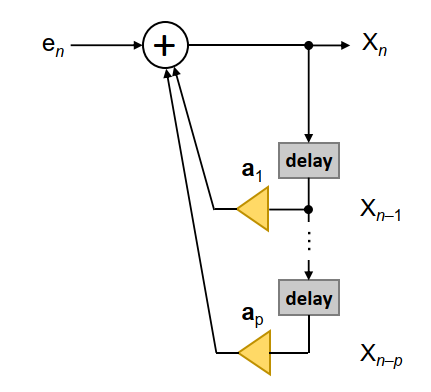

# Plot

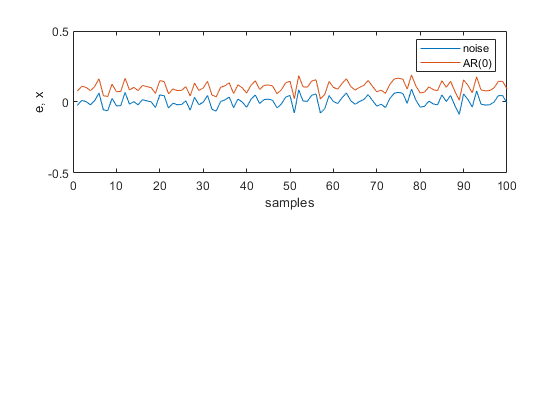

figure();
subplot(2, 1, 1);
plot(e);
hold on;
plot(x);
ylim([0, N]); %xlim(0, N);
ylim([-0.5, 0.5]); %ylim(-2, 2);
xlabel('samples');
ylabel('e, x') ;
% legend(['noise', 'AR(0)'], loc='best');
% tight_layout(pad=0.5, w_pad=0.5, h_pad=1.0);
legend('noise', 'AR(0)')

# AR(1)


$$X_n =c+\sum_{i=1}^p a_i X_{n-i} +e_n$$


透過改變$a_i$增益來做，AR(1)，表示找前一個採樣 $X_{n-i}$與一個增益$a_i$乘得到結果, delay 1 sampe。

[Autoregressive for forecast error](https://youtu.be/4WWQWeMXvas): Youtube

delay 不能超過sample數量

Only for short-term forecasts

To forcast k-steps ahead($$$\mathrm{F}_{\mathrm{t}+\mathrm{k}}$$$)

Use AR(p) model only if k>p, p  lag p sequence, k is steps

a = [];
p = length(a)+1; % matlab counter 不能從零開始 所以不用 `i = p:N`

a = [0.1, 0.9, -0.9, 0.3, 0.5]; % close to 0, 1
x = zeros(N,5); % 初始化矩陣大小

x(1,1) = a(1).*x(1,1)+e(1);
x(1,2) = a(2).*x(1,2)+e(1);
x(1,3) = a(3).*x(1,3)+e(1);
x(1,4) = a(4).*x(1,4)+e(1);
x(1,5) = a(5).*x(1,5)+e(1);
lag = 1;
for i = (p+lag):N
    x(i,1) = a(1).*x(i-1,1)+e(i);
    x(i,2) = a(2).*x(i-1,2)+e(i);
    x(i,3) = a(3).*x(i-1,3)+e(i);
    x(i,4) = a(4).*x(i-1,4)+e(i);
    x(i,5) = a(5).*x(i-1,5)+e(i);
end

# Plot

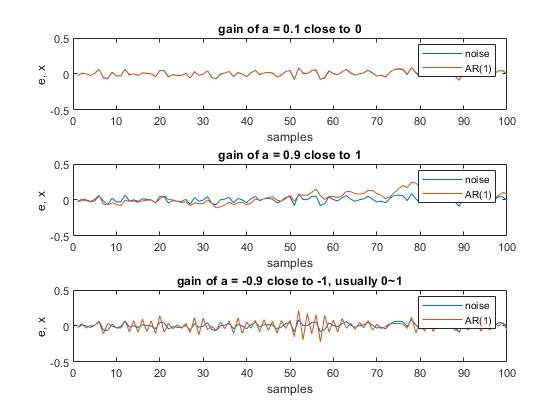

figure();
subplot(3, 1, 1);
plot(e);
hold on;
plot(x(:,1));
title('gain of a = 0.1 close to 0');
ylim([0, N]); %xlim(0, N);
ylim([-0.5, 0.5]); %ylim(-2, 2);
xlabel('samples');
ylabel('e, x') ;
% legend(['noise', 'AR(0)'], loc='best');
% tight_layout(pad=0.5, w_pad=0.5, h_pad=1.0);
legend('noise', 'AR(1)')
subplot(3, 1, 2);
plot(e);
hold on;
plot(x(:,2));
title('gain of a = 0.9 close to 1')
xlim([0, N]); %xlim(0, N);
ylim([-0.5, 0.5]); %ylim(-2, 2);
xlabel('samples');
ylabel('e, x') ;
% legend(['noise', 'AR(0)'], loc='best');
% tight_layout(pad=0.5, w_pad=0.5, h_pad=1.0);
legend('noise', 'AR(1)')
subplot(3, 1, 3);
plot(e);
hold on;
plot(x(:,3));
title('gain of a = -0.9 close to -1, usually 0~1')
xlim([0, N]); %xlim(0, N);
ylim([-0.5, 0.5]); %ylim(-2, 2);
xlabel('samples');
ylabel('e, x') ;
% legend(['noise', 'AR(0)'], loc='best');
% tight_layout(pad=0.5, w_pad=0.5, h_pad=1.0);
legend('noise', 'AR(1)')

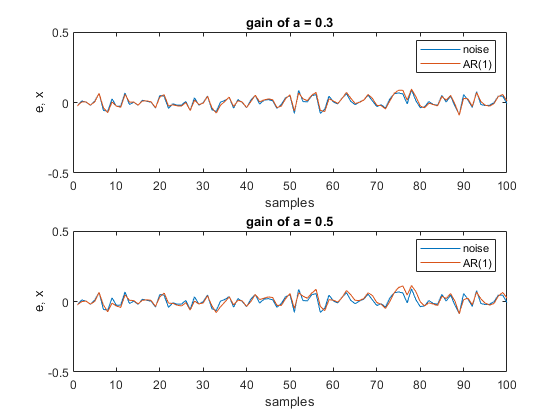

figure();
subplot(2, 1, 1);
plot(e);
hold on;
plot(x(:,4));
title('gain of a = 0.3');
xlim([0, N]); %xlim(0, N);
ylim([-0.5, 0.5]); %ylim(-2, 2);
xlabel('samples');
ylabel('e, x') ;
% legend(['noise', 'AR(0)'], loc='best');
% tight_layout(pad=0.5, w_pad=0.5, h_pad=1.0);
legend('noise', 'AR(1)')
subplot(2, 1, 2);
plot(e);
hold on;
plot(x(:,5));
title('gain of a = 0.5')
xlim([0, N]); %xlim(0, N);
ylim([-0.5, 0.5]); %ylim(-2, 2);
xlabel('samples');
ylabel('e, x') ;
% legend(['noise', 'AR(0)'], loc='best');
% tight_layout(pad=0.5, w_pad=0.5, h_pad=1.0);
legend('noise', 'AR(1)')

# AR(2) lag 2 seq

a = [];
p = length(a)+1; % matlab counter 不能從零開始 所以不用 `i = p:N`

a = [0.1, 0.9, -0.9 ,0.3, 0.5]; % close to 0, 1
x = zeros(N,5); % 初始化矩陣大小
lag = 2;
for j =1:lag % lag
    for i = 1:5 % which data
        x(j,i) = a(j).*x(j,i)+e(j);
    end
end

for i = (p+lag):N
    x(i,1) = a(1).*x(i-2,1)+e(i);
    x(i,2) = a(2).*x(i-2,2)+e(i);
    x(i,3) = a(3).*x(i-2,3)+e(i);
    x(i,4) = a(4).*x(i-2,4)+e(i);
    x(i,5) = a(5).*x(i-2,5)+e(i);
end

# Plot

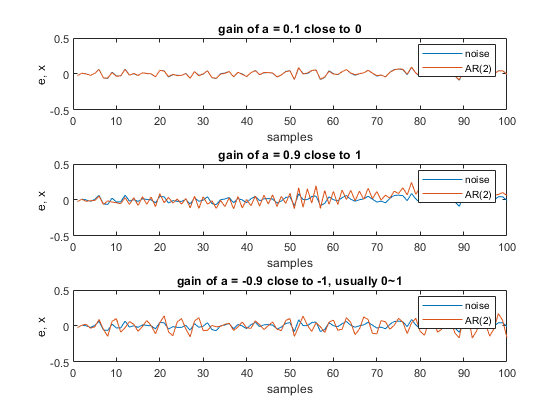

figure();
subplot(3, 1, 1);
plot(e);
hold on;
plot(x(:,1));
title('gain of a = 0.1 close to 0');
xlim([0, N]); %xlim(0, N);
ylim([-0.5, 0.5]); %ylim(-2, 2);
xlabel('samples');
ylabel('e, x') ;
% legend(['noise', 'AR(2)'], loc='best');
% tight_layout(pad=0.5, w_pad=0.5, h_pad=1.0);
legend('noise', 'AR(2)')
subplot(3, 1, 2);
plot(e);
hold on;
plot(x(:,2));
title('gain of a = 0.9 close to 1')
xlim([0, N]); %xlim(0, N);
ylim([-0.5, 0.5]); %ylim(-2, 2);
xlabel('samples');
ylabel('e, x') ;
% legend(['noise', 'AR(2)'], loc='best');
% tight_layout(pad=0.5, w_pad=0.5, h_pad=1.0);
legend('noise', 'AR(2)')
subplot(3, 1, 3);
plot(e);
hold on;
plot(x(:,3));
title('gain of a = -0.9 close to -1, usually 0~1')
xlim([0, N]); %xlim(0, N);
ylim([-0.5, 0.5]); %ylim(-2, 2);
xlabel('samples');
ylabel('e, x') ;
% legend(['noise', 'AR(2)'], loc='best');
% tight_layout(pad=0.5, w_pad=0.5, h_pad=1.0);
legend('noise', 'AR(2)')

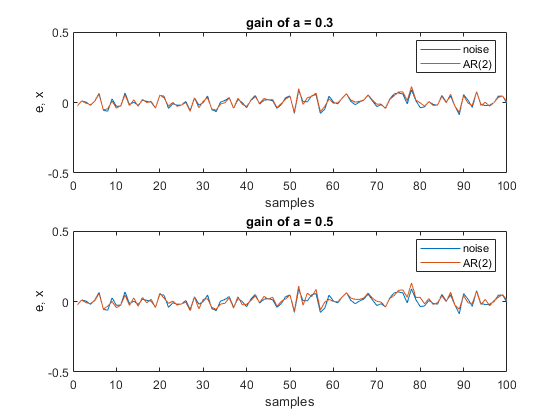

figure();
subplot(2, 1, 1);
plot(e);
hold on;
plot(x(:,4));
title('gain of a = 0.3');
xlim([0, N]); %xlim(0, N);
ylim([-0.5, 0.5]); %ylim(-2, 2);
xlabel('samples');
ylabel('e, x') ;
% legend(['noise', 'AR(0)'], loc='best');
% tight_layout(pad=0.5, w_pad=0.5, h_pad=1.0);
legend('noise', 'AR(2)')
subplot(2, 1, 2);
plot(e);
hold on;
plot(x(:,5));
title('gain of a = 0.5')
xlim([0, N]); %xlim(0, N);
ylim([-0.5, 0.5]); %ylim(-2, 2);
xlabel('samples');
ylabel('e, x') ;
% legend(['noise', 'AR(0)'], loc='best');
% tight_layout(pad=0.5, w_pad=0.5, h_pad=1.0);
legend('noise', 'AR(2)')